assert(isfile("DCS_2D_Cylinder.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

cylinder.radius = 30e-3; % (m)
cylinder.height = 20e-3; % (m)
cylinder.n_r = 20;
cylinder.n_z = 20;

## Uniform Grid

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length  = 4.00e-3; % length (m)

EM.z = 5.00e-3; % (m)

EM.current = 1; % (A)
EM.Nturns = 60;
EM.current_density = EM.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.angular_frequency = 2*pi*2000; % (rad/s)

#### Model

r = linspace(0, cylinder.radius, cylinder.n_r+1);
z = linspace(-cylinder.height,0, cylinder.n_z+1);

Model = BuildCylinderModel(r,z, 'uniform_grid');

calculate geometry took 0.01 seconds


clear r z

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 37.74 seconds


#### Solve in frequency domain

Sol = SolveFrequency2D(GoverningEquation, EM);

solve J_Im took 0.00 seconds
solve J_Re took 0.00 seconds


#### Plot result

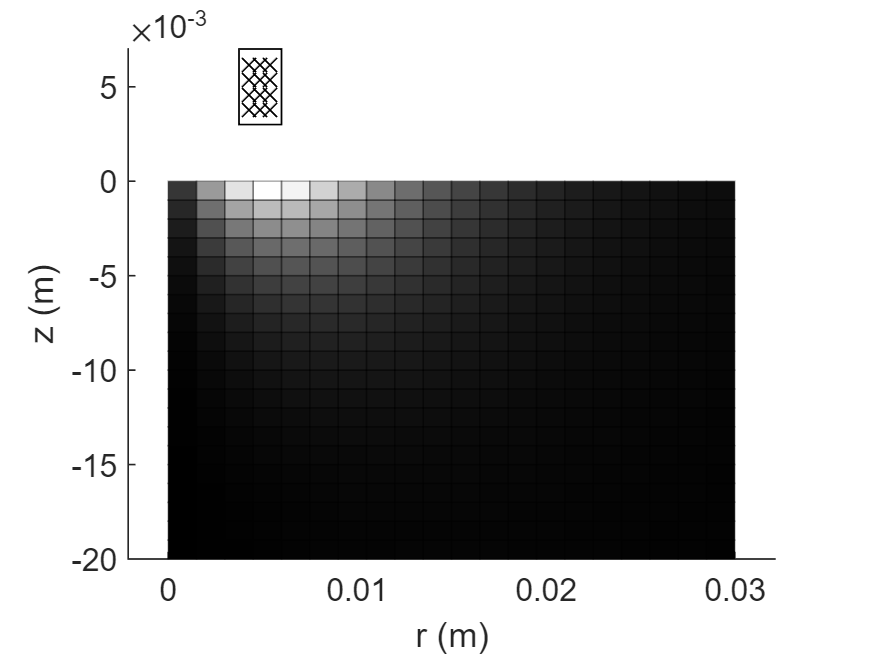

J = hypot(Sol.J_Re, Sol.J_Im);
PlotWorld2D(Model, EM, J);

## Adaptive Grid

#### Model

pdf = reshape(J.^-0.5, [cylinder.n_r, cylinder.n_z]);
r_cdf = cumsum(pdf(:,end))';  r_cdf = [0 r_cdf] / r_cdf(end);
z_cdf = cumsum(pdf(5,:));     z_cdf = [0 z_cdf] / z_cdf(end);

r = cylinder.radius * r_cdf;
z = cylinder.height * z_cdf - cylinder.height;

Model2 = BuildCylinderModel(r,z, 'adaptive_grid');

calculate geometry took 0.00 seconds


clear pdf r_cdf z_cdf r z

#### Plot adaptive grid

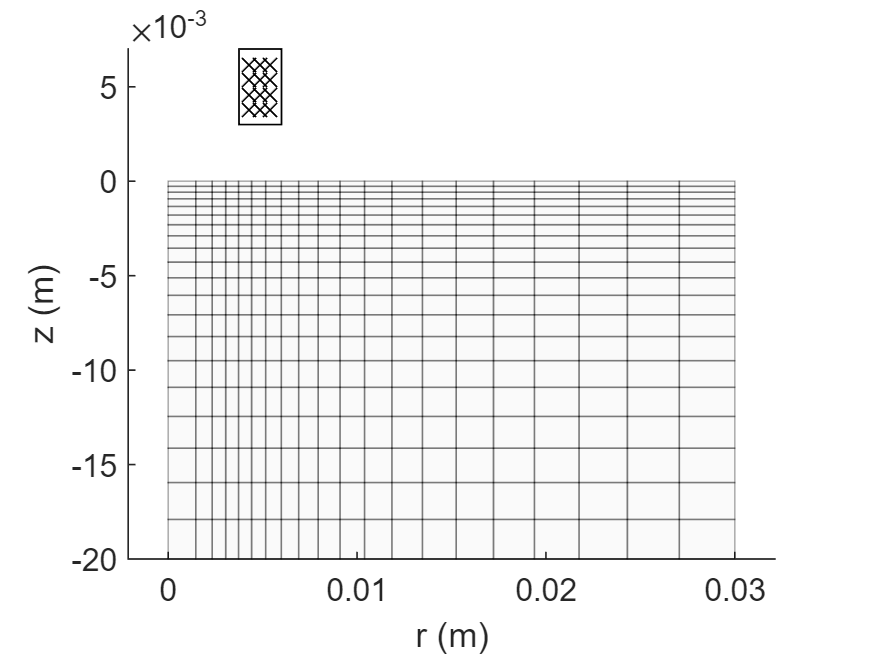

clf;
PlotWorld2D(Model2, EM);